**Crie um conjunto de funções Matlab que implementem as funcionalidades de um Bloom Filter básico. As**

**funções devem ter os parâmetros necessários para que seja possível criar Bloom Filters de diferentes tamanhos**

**(n) e a utilização de diferentes números de funções de dispersão (k).**

**Na criação das diferentes funções de dispersão, adote o terceiro método descrito no slide “Como ter n**

**funções de dispersão ?” da apresentação TP sobre funções de dispersão com a função que considera ter tido o**

**melhor desempenho na experiências que efetuou na secção 6.2.**

**Sugestão: Criar pelo menos 3 funções: uma para inicializar a estrutura de dados; outra para inserir um**

**elemento (ou elementos) no filtro; uma terceira para verificar se um elemento pertence ao conjunto.**

function hash = string2hash(str,type)
    str=double(str);
    if(nargin<2), type='djb2'; 
    end
    switch(type)
        case 'djb2'
            hash = 5381*ones(size(str,1),1); 
            for i=1:size(str,2) 
                hash = mod(hash * 33 + str(:,i), 2^32-1); 
            end
        case 'sdbm'
            hash = zeros(size(str,1),1);
            for i=1:size(str,2) 
                hash = mod(hash * 65599 + str(:,i), 2^32-1);
            end
        otherwise
            error('string_hash:inputs','unknown type');
    end
end

function hash = multiple_hash(str,k)
    if(nargin<2), k=1; end
    hash = zeros(1, k);
    hash(1) = string2hash(str,'sdbm');
    if k > 1
        for i = 2:k
            hash(i) = string2hash(num2str(hash(i - 1)),'sdbm');
        end
    end
end

function bloom_filter_table = bloom_filter(conjunto, n, k)
    bloom_filter_table = zeros(1, n);
    for i = 1:size(conjunto, 2)
        elem_hashes = multiple_hash(conjunto{i}, k);
        for z = 1:k
            idx = mod(elem_hashes(z), n) + 1;
            bloom_filter_table(idx) = 1;
        end
    end
end

**1. **Com as funções que desenvolveu, crie um Bloom Filter para guardar um conjunto, U1, de 1000 palavras

diferentes. Use um Bloom Filter de tamanho n = 8000 e k = 3 funções de dispersão.

function chaves_geradas = gerar_chaves(chaves_a_gerar, imin, imax, caracteres, prob_characteres)
    if nargin < 5
        prob_characteres = ones(1, length(caracteres)) / length(caracteres);
    end
    chaves_geradas = cell(1, chaves_a_gerar);
    for i = 1:chaves_a_gerar
        comprimento = randi([imin, imax]);
        chave = randsample(caracteres, comprimento, true, prob_characteres);
        chaves_geradas{i} = char(chave);
    end
end

N = 1000;
imin = 3;
imax = 10;
caracteres = 'A':'Z';
prob_characteres = [];

U1 = gerar_chaves(N, imin, imax, caracteres, prob_characteres)

U1 = 1×1000 cell array
    {'RJIALVQ'}    {'PNBRKGTWOL'}    {'CJABQNOHRQ'}    {'PLSZNUZQ'}    {'PQXQY'}    {'FLWJC'}    {'XERNWHHFD'}    {'RUNVGSWCZS'}    {'YZK'}    {'VBWEVVN'}    {'JYSZZCJ'}    {'CSJCYFA'}    {'REEXCBAOI'}    {'KQQIYIR'}    {'WIX'}    {'CHHQ'}    {'SDJQWMR'}    {'BVC'}    {'URMX'}    {'RYHSTE'}    {'BRRDXEO'}    {'VPK'}    {'JZSFVHNQ'}    {'UFF'}    {'HVZKXNCKA'}    {'JANLWNCUYW'}    {'CQCA'}    {'QPRUJ'}    {'LUH'}    {'CEYUUWXY'}    {'HTYHJH'}    {'YCOHDK'}    {'OEFOX'}    {'XTLDYPIH'}    {'VYWONNQ'}    {'NIHJZ'}    {'LVNOTHKTM'}    {'XIHQEFUC'}    {'FJOGSIAV'}    {'HHN'}    {'UNF'}    {'CZTNMHZIL'}    {'UKXDWQL'}    {'AJAM'}    {'VYFT'}    {'NDQ'}    {'BODJ'}    {'AVXL'}    {'JHVZF'}    {'LKWNFSLK'}    {'DALYTIEZWR'}    {'XGWKC'}    {'VYQZQLHVYY'}    {'EYQO'}    {'ZVXOILGD'}    {'PFMUPXTVS'}    {'QPAOWLICX'}    {'XNLAGU'}    {'QSCT'}    {'TFEXHELXES'}    {'HHYFJRJRZ'}    {'SGWUDGON'}    {'UGCUSYKGTK'}    {'EZODNGW'}    {'PIZREGTOBO'}    {'SZXPSVREDI'}    {'AGARWUO


bloom_filter1 = bloom_filter(U1, 8000, 3)

bloom_filter1 =      0     1     0     0     0     0     1     0     1     0     0     0     0     0     1     1     0     1     1     0     0     0     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     1     0


sum(bloom_filter1)

ans = 2506

**2.** Teste o Bloom Filter criado anteriormente, verificando a pertença de todas as palavras do conjunto U1.

Obteve algum falso negativo?

function output = in_bloom_filter(element, bloom_filter_table, n, k)
    elem_hashes = multiple_hash(element, k);
    probably_yes = 0;
    for i = 1:k
        idx = mod(elem_hashes(i), n) + 1;
        if bloom_filter_table(idx) == 1
            probably_yes = probably_yes + 1;
        end
    end
    if probably_yes == k
        output = 1;
    else
        output = 0;
    end
end

falsos_negativos = 0;
for i = 1:1000
    if in_bloom_filter(U1{i}, bloom_filter1, 8000, 3) == 0
        falsos_negativos = falsos_negativos + 1;
    end
end

fprintf('Numero de falsos negativos: %d', falsos_negativos)

Numero de falsos negativos: 0

**3. **Teste o Bloom Filter criado anteriormente, verificando a pertença de um novo conjunto, U2, com 100000

palavras todas diferentes das de U1. Indique a percentagem de falsos positivos obtidos.

N = 100000;
imin = 3;
imax = 10;
caracteres = 'a':'z';
prob_characteres = [];

U2 = gerar_chaves(N, imin, imax, caracteres, prob_characteres)

U2 = 1×100000 cell array
  Columns 1 through 2264

    {'cgsj'}    {'pfo'}    {'wfdywxpvy'}    {'fovgpteql'}    {'ilfpzanqp'}    {'aikoaeygz'}    {'jerq'}    {'msn'}    {'pcwpwcxty'}    {'gtmiq'}    {'skne'}    {'tvhdn'}    {'dif'}    {'bgvqgle'}    {'iyb'}    {'ewpzudmv'}    {'luk'}    {'lwl'}    {'svylx'}    {'iwfoo'}    {'sstjz'}    {'hpxe'}    {'wluxzgwbt'}    {'cjz'}    {'nehskjprr'}    {'qctcozoelx'}    {'cibxn'}    {'qhvijevzf'}    {'cnfvooov'}    {'szneyuhvv'}    {'nhqeymqlrg'}    {'osva'}    {'ddexmr'}    {'vzmlvren'}    {'lbpmu'}    {'lkuzmji'}    {'yqpurfyjeu'}    {'owgruxkop'}    {'ppdjzi'}    {'cqjujvh'}    {'gqzcfgt'}    {'pnjilr'}    {'bedb'}    {'jgo'}    {'dqqrksqz'}    {'dusrzqmfa'}    {'sxcdsp'}    {'iubabpjjq'}    {'bfjpur'}    {'nrfmuny'}    {'zvg'}    {'wosvi'}    {'cvvm'}    {'grdmuj'}    {'srikuzbjqi'}    {'vooexvqcyh'}    {'slnsoq'}    {'dbf'}    {'pkhh'}    {'efdktzej'}    {'xrvnjhzf'}    {'fftplggm'}    {'fvdn'}    {'rrmpjgpoxg'}    {'ebcegkcp'}    {'fvvpcgvn


falsos_positivos = 0;
for i = 1:N
    if in_bloom_filter(U2{i}, bloom_filter1, 8000, 3) == 1
        falsos_positivos = falsos_positivos + 1;
    end
end

percentagem_falsos_positivos = falsos_positivos/N;
fprintf('Percentagem de Falsos Positivos: %.4f', percentagem_falsos_positivos)

Percentagem de Falsos Positivos: 0.0308

**4. **Compare a percentagem de falsos positivos obtida anteriormente com a estimativa que aprendeu nas TPs.

n = 8000;
m = 1000;
k = 3;     

falso_positivo_teorico = (1 - exp(-k * m / n))^k;

fprintf('Falsos positivos teóricos: %.4f\n', falso_positivo_teorico);

Falsos positivos teóricos: 0.0306


fprintf('Falsos positivos observados: %.4f\n', percentagem_falsos_positivos);

Falsos positivos observados: 0.0308


**5. **Repita os exercícios 1 e 3 para um número de funções de dispersão k de 4 até 10. Faça um gráfico

com a percentagem de falsos positivos em função de k. Analisando os resultados, qual o valor ótimo k?

Compare este valor com o valor teórico que aprendeu nas TPs.

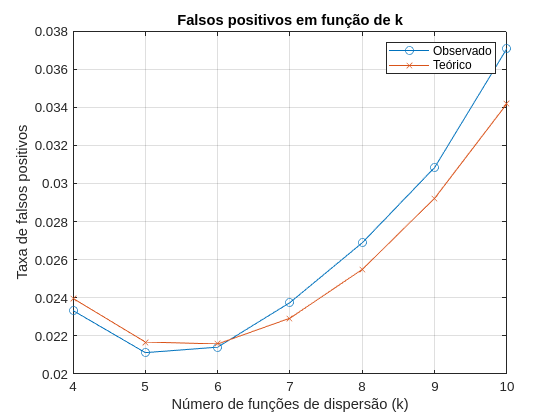

n = 8000;
m = 1000;
k = 4:10;
percentagem_falsos_positivos = zeros(1, length(k));
falsos_positivo_teorico = zeros(1, length(k));

% Conjunto U2 para o teste
N = 100000;
imin = 3;
imax = 10;
caracteres = 'a':'z';
prob_characteres = [];
U2 = gerar_chaves(N, imin, imax, caracteres, prob_characteres);

for i = 1:length(k)
    current_k = k(i);
    
    % Gerar Bloom Filter
    bloom_filter1 = bloom_filter(U1, n, current_k);
    
    % Calcular falsos positivos observados
    falsos_positivos = 0;
    for z = 1:N
        if in_bloom_filter(U2{z}, bloom_filter1, n, current_k) == 1
            falsos_positivos = falsos_positivos + 1;
        end
    end
    percentagem_falsos_positivos(i) = falsos_positivos / N;
    
    % Calcular falsos positivos teóricos
    falsos_positivo_teorico(i) = (1 - exp(-current_k * m / n))^current_k;
end

figure
plot(k, percentagem_falsos_positivos, '-o', 'DisplayName', 'Observado');
hold on;
plot(k, falsos_positivo_teorico, '-x', 'DisplayName', 'Teórico');
xlabel('Número de funções de dispersão (k)');
ylabel('Taxa de falsos positivos');
title('Falsos positivos em função de k');
legend('show');
grid on;


otimo_teorico = round((n / m) * log(2));
fprintf('Valor ótimo teórico de k: %d\n', otimo_teorico);

Valor ótimo teórico de k: 6
